Vectorisation de la surface de Van der Walls sans correction

% Paramètres
Npas = 100; % nombre de coupes
Vmax = 4;
Vmin = 0.4;
Tmax = 2; % Tr = 1 => T = Tc
Tmin = 0.4;
pts = linspace(-1, 1, Npas);

% transformation affine
V = ((Vmax - Vmin)/2)*pts + (Vmax+Vmin)/2;
T = ((Tmax - Tmin)/2)*pts + (Tmax+Tmin)/2;
% le travail avec un meshgrid est optionnel mais il faudra utiliser
% delaunayTriangulation plutot que delaunay pour la triangulation si
% le travail est fait sans meshgrid
[V,T] = meshgrid(V,T); 
P = (8*T)./(3.*V-1) - 3./(V.^2);

% thresholding avec les seuils choisis
P(P > 2) = 2;
P(P < 0) = 0;

%% visualiser V,T,P

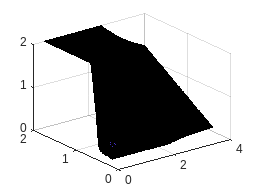

% visualisation
connect = delaunay(V,T);
trisurf(connect, V,T,P);

% normalisation avec une transformation affine

V_norm = normalisation(Vmin,Vmax,V);
T_norm = normalisation(Tmin, Tmax, T);
P_norm = normalisation(min(min(P)), max(max(P)), P);

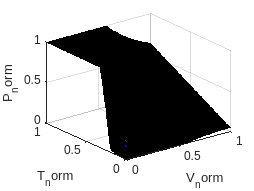

% visualisation
trisurf(connect, V_norm, T_norm, P_norm)
xlabel("V_norm")
ylabel('T_norm')
zlabel("P_norm")

%%% fermeture de la figure
% extraction des bords 
vmin = min(min(V_norm));
vmax = max(max(V_norm));
tmin = min(min(T_norm));
tmax = max(max(T_norm));

%% à gauche (si on regarde la figure de façon que Vsnorm soit en face de nous)
xq = linspace(vmin,vmin,Npas);
yq = linspace(tmin,tmax,Npas);
zq = interp2(V_norm,T_norm,P_norm,xq,yq);

% triangulation
YQ = [yq yq];
ZQ = [zq linspace(0,0,Npas)];

sommets_g = reshape([YQ ZQ], [], 2);
connect_g = [];
for i=1:Npas-1
    connect_g=[connect_g [Npas+i Npas+i+1 i] [i i+1 Npas+i+1]];
end
connect_g=transpose(reshape(connect_g, 3, []));

% Ajout dans connect
connect_g = connect_g + max(max(connect));
connect(end+(1:2*Npas-2),:) = connect_g;
sommet_g_3d = reshape([repmat(vmin,1,2*Npas) YQ ZQ],[],3); % save this

%% à droite (si on regarde la figure de façon que Vsnorm soit en face de nous)
xq = linspace(vmax,vmax,Npas);
yq = linspace(tmin,tmax,Npas);
zq = interp2(V_norm,T_norm,P_norm,xq,yq);

% triangulation
YQ = [yq yq];
ZQ = [zq linspace(0,0,Npas)];

sommets_d = reshape([YQ ZQ], [], 2);
connect_d = [];
for i=1:Npas-1
    connect_d=[connect_d [Npas+i Npas+i+1 i] [i i+1 Npas+i+1]];
end
connect_d=transpose(reshape(connect_d, 3, []));

% Ajout dans connect
connect_d = connect_d + max(max(connect));
connect(end+(1:2*Npas-2),:) = connect_d;
sommet_d_3d = reshape([repmat(vmax,1,2*Npas) YQ ZQ],[],3); % save this

%% devant (si on regarde la figure de façon que Vsnorm soit en face de nous)
xq = linspace(vmin,vmax,Npas);
yq = linspace(tmin,tmin,Npas);
zq = interp2(V_norm,T_norm,P_norm,xq,yq);

% triangulation
XQ = [xq xq];
ZQ = [zq linspace(0,0,Npas)];

sommets_dev = reshape([XQ ZQ], [], 2);
connect_dev = [];
for i=1:Npas-1
    connect_dev=[connect_dev [Npas+i Npas+i+1 i] [i i+1 Npas+i+1]];
end
connect_dev=transpose(reshape(connect_dev, 3, []));

% Ajout dans connect
connect_dev = connect_dev + max(max(connect));
connect(end+(1:2*Npas-2),:) = connect_dev;
sommet_dev_3d = reshape([XQ repmat(tmin,1,2*Npas) ZQ],[],3); % save this

%% derrière (si on regarde la figure de façon que Vsnorm soit en face de nous)
xq = linspace(vmin,vmax,Npas);
yq = linspace(tmax,tmax,Npas);
zq = interp2(V_norm,T_norm,P_norm,xq,yq);

% triangulation
XQ = [xq xq];
ZQ = [zq linspace(0,0,Npas)];

sommets_der = reshape([XQ ZQ], [], 2);
connect_der = [];
for i=1:Npas-1
    connect_der=[connect_der [Npas+i Npas+i+1 i] [i i+1 Npas+i+1]];
end
connect_der=transpose(reshape(connect_der, 3, []));

% Ajout dans connect
connect_der = connect_der + max(max(connect));
connect(end+(1:2*Npas-2),:) = connect_der;
sommet_der_3d = reshape([XQ repmat(tmax,1,2*Npas) ZQ],[],3); % save this

% sauvegarde en stl
sommet = reshape([reshape(V_norm,[],1) reshape(T_norm,[],1) reshape(P_norm, [], 1)], [], 3);
sommet(end+(1:2*Npas),:) = sommet_g_3d;
sommet(end+(1:2*Npas),:) = sommet_d_3d;
sommet(end+(1:2*Npas),:) = sommet_dev_3d;
sommet(end+(1:2*Npas),:) = sommet_der_3d;

%fermeture en bas
maxi = max(max(connect));
sommet(end+1,:)=[vmin tmin 0];
sommet(end+1,:)=[vmin tmax 0];
sommet(end+1,:)=[vmax tmax 0];
sommet(end+1,:)=[vmax tmin 0];
connect(end+1,:)=[maxi+1 maxi+2 maxi+4];
connect(end+1,:)=[maxi+2 maxi+3 maxi+4];

tri = triangulation(connect, sommet);
stlwrite(tri, 'loi_vdw.stl')